# Assignment 7 Exercise 4

Part a

a = 3;
b = 40;

f = @(x) a*x.^2 + b*x;

Part b

x = -20:20;
plot(x,f(x))

Part c

[xm,f0] = fminsearch(f, 0)

xm = -6.6667

f0 = -133.3333

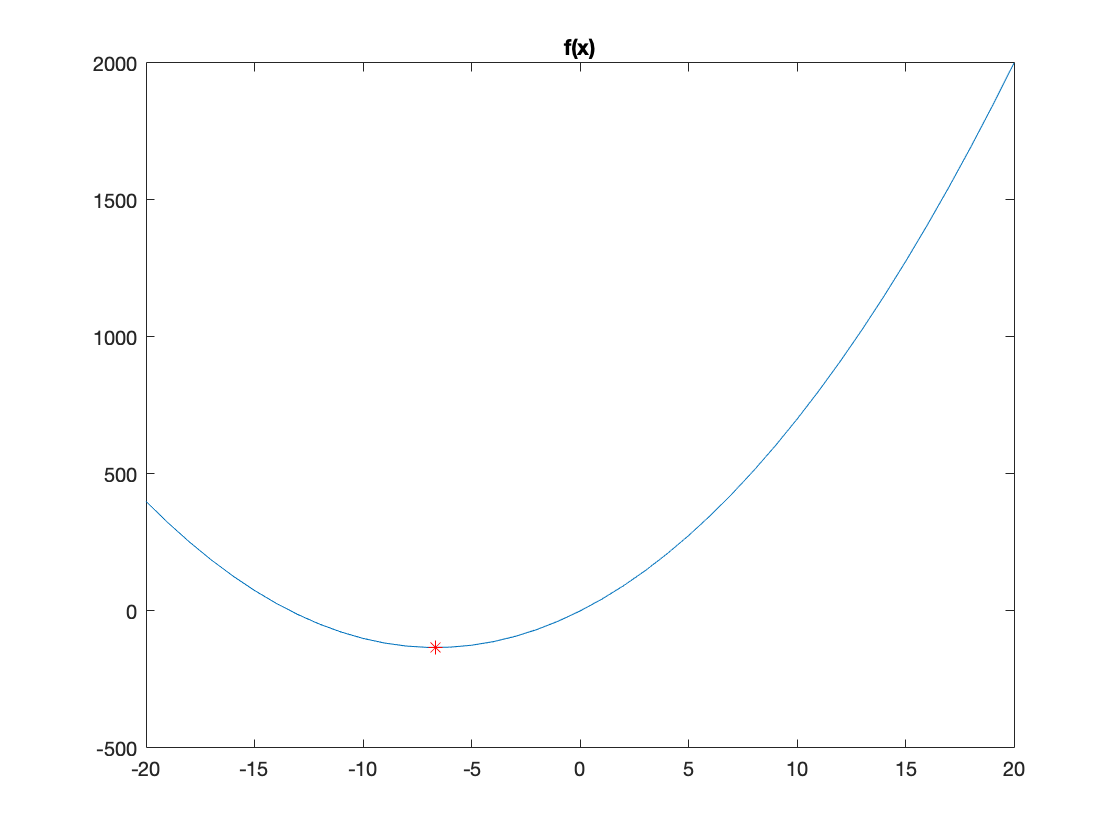

hold on
plot(xm, f0, 'r*')
title('f(x)')

Part d

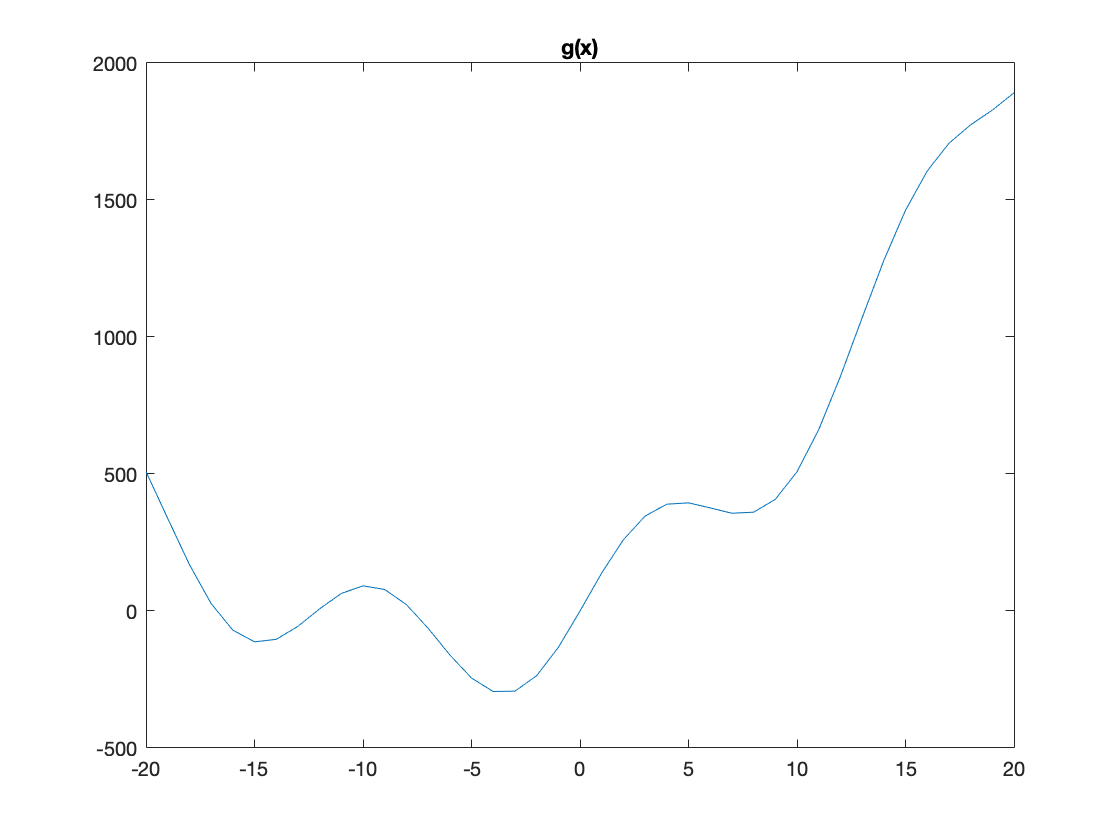

c = 200;
g = @(x) f(x)+c*sin(x/2);
figure();
plot(x, g(x));
title('g(x)')

Part e

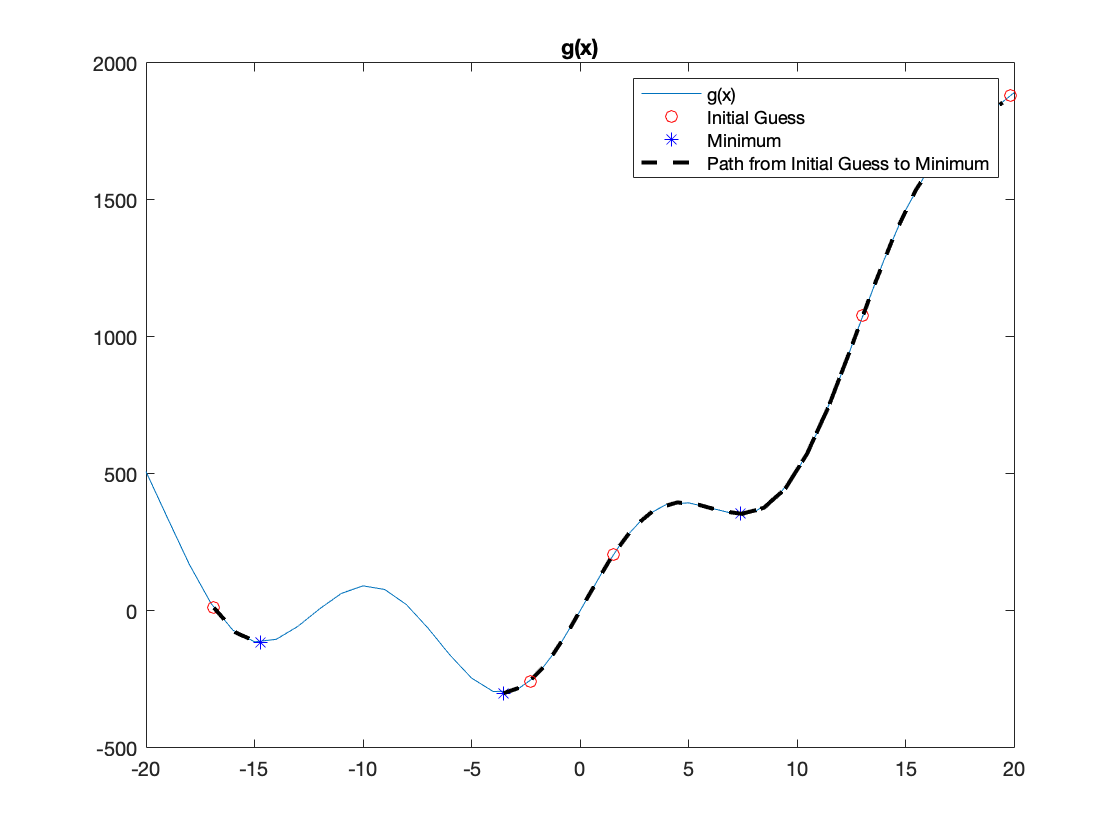

for i = 1:5
    x0 = rand*40-20; % Random value between -20 and 20
    [xm,gm] = fminsearch(g, x0);

    hold on
    plot(x0, g(x0), 'ro') % Initial Value
    plot(xm,gm, 'b*') % Min
    % Between these two calls, the path between x0 and xm is plotted
    xf1=x0:xm;
    xf2=xm:x0;
    plot(xf1,g(xf1), 'k--', 'LineWidth', 2)
    plot(xf2,g(xf2), 'k--', 'LineWidth', 2)

end
legend("g(x)", "Initial Guess", "Minimum", "Path from Initial Guess to Minimum")

%The solution does not always point to the global minimum becuase the way
% matlab approxmates the minimum, it may assume a local minimum is the
% minimum.